En la figura que se muestra a continuación se ubicaron los sistemas coordenados sobre las articulaciones del robot para establecer el modelo DH módificado.

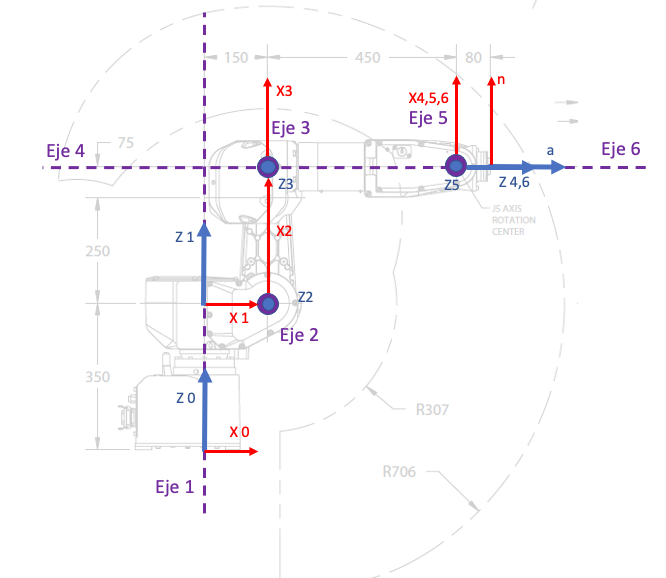

Utilizando los objetos Link y SerialLink del Toolbox de Peter Corke para crear el robot.

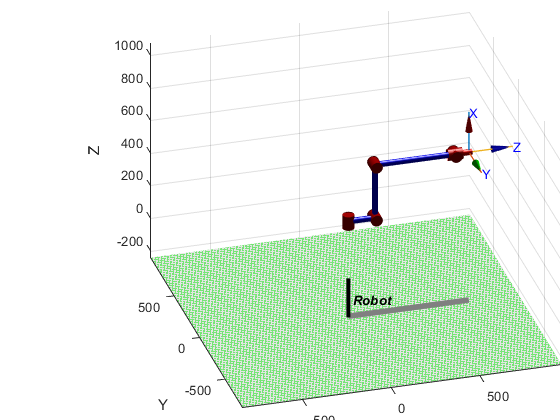

l0 = 350; l1 = 150; l2 = 250+75; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]*12;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha',     0,'a',   0, 'd',  l0,'offset',   0, 'qlim',        [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha',  pi/2,'a',  l1, 'd',   0,'offset',pi/2, 'qlim',       [-5*pi/6 7*pi/36],   'modified');
L(3) = Link('revolute'  ,'alpha',     0,'a',  l2, 'd',   0,'offset',   0, 'qlim',   [-17*pi/36 47*pi/36],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',  l3,'offset',   0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',        [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',            [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
Robot.teach()
view([-16 28])


MTH01 = L(1).A(0);
MTH12 = L(2).A(0);
MTH23 = L(3).A(0);
MTH34 = L(4).A(0);
MTH45 = L(5).A(0);
MTH56 = L(6).A(0);
MTH6T = Robot.tool;

Posteriormente, utilizando el Robotics Systems Toolbox se crean los eslabones del robot con sus respectivas articulaciones para posteriormente ensamblarlos entre sí en un árbol de cuerpos rigidos como se ilustra a continuación.

robotRST = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
tform1 = trvec2tform([0 0 l0]);
setFixedTransform(jnt1,tform1);
body1.Joint = jnt1;

addBody(robotRST,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0;
tform2 = trvec2tform([l1 0 0])*eul2tform([0 -pi/2 pi/2]);
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;

addBody(robotRST,body2,'body1')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
tform3 = trvec2tform([l2 0 0]);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;

addBody(robotRST,body3,'body2')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
tform4 = trvec2tform([0 -l3 0])*eul2tform([0 0 pi/2]);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;

addBody(robotRST,body4,'body3')

body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
tform5 = eul2tform([0 0 -pi/2]);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;

addBody(robotRST,body5,'body4')

body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
tform6 = eul2tform([0 0 pi/2]);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;

addBody(robotRST,body6,'body5')

bodyEndEffector = rigidBody('endeffector');
tformEfec = trvec2tform([0 0 l4]);
setFixedTransform(bodyEndEffector.Joint,tformEfec);
addBody(robotRST,bodyEndEffector,'body6');

figure()
show(robotRST)

ans =   Axes (Primary) with properties:

             XLim: [-1152 1152]
             YLim: [-1152 1152]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


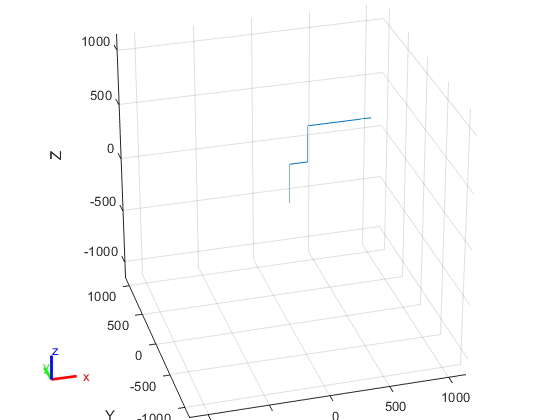


view([-16 28])
hold off

Comparando los resultados obtenidos con ambos Toolbox para hallar la posición del efector final respecto a la base en la configuración de home, se puede ver que los resultados son consistentes entre ambos métodos.

MTH0T = MTH01*MTH12*MTH23*MTH34*MTH45*MTH56*MTH6T

MTH0T =     0.0000   -0.0000    1.0000  680.0000
    0.0000   -1.0000   -0.0000   -0.0000
    1.0000    0.0000   -0.0000  675.0000
         0         0         0    1.0000


config = homeConfiguration(robotRST);
tform = getTransform(robotRST,config,'endeffector','base')

tform =     0.0000   -0.0000    1.0000  680.0000
         0   -1.0000   -0.0000   -0.0000
    1.0000    0.0000   -0.0000  675.0000
         0         0         0    1.0000


Utilizando la hoja técnica del controlador R-J3iB se puede ver que se tiene la siguiente configuración para realizar las pruebas de calibración del robot utilizando cinemática directa.

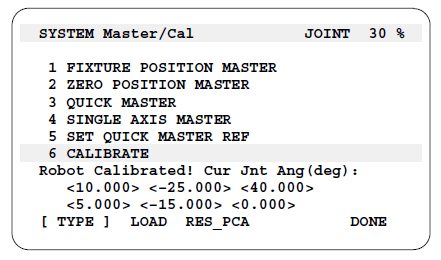

A continuación se procede a probar este punto de calibración utilizando los métodos de cinemática directa de cada uno de los Toolbox trabajdos.

q = deg2rad([10,-25,40,5,-15,0]);
Robot.fkine(q)

ans =     0.0156    0.1952    0.9806  789.4997
   -0.0827   -0.9771    0.1958  141.0425
    0.9964   -0.0842    0.0010  761.0947
         0         0         0    1.0000


c1 = num2cell(q);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base')

tform =     0.0156    0.1952    0.9806  789.4997
   -0.0827   -0.9771    0.1958  141.0425
    0.9964   -0.0842    0.0010  761.0947
         0         0         0    1.0000
